# Extraction of context-specific models

## Authors: Thomas Pfau, Systems Biochemistry Group, University of Luxembourg - Anne Richelle, Systems Biology and Cell Engineering, University of California San Diego

## INTRODUCTION

Genome-scale reconstruction of metabolism (GEM) can illuminate the molecular basis of cell phenotypes exhibited by an organism. Since some enzymes are only active in specific cell types or environmental conditions, several algorithms have been developed to extract context-specific models that capture the metabolism of individual tissues or cell types. Therefore, a context-specific model is a subset of the GEM, in which inactive reactions are removed. Reaction removal is determined by the algorithm used, gene expression levels, presence of proteins or metabolites, experimental data availability, literature knowledge, and/or predefined metabolic functions of the cell type that need to be maintained in the extracted model. These decisions on methodology and data processing significantly influence the size, functionality and accuracy of constructed context-specific models. While there is no strong evidence that one model extraction method (MEM) universally gives the most physiologically accurate models, each method has different underlying assumptions that affect the resulting model. Therefore, selection of the MEM and the associated parameters should be done while considering the goals of the study and the available data [1].  	 

Multiple algorithms have been suggested to automatically derive context specific networks from a generic reconstruction and a set of transcriptomic or proteomic data. The COBRA toolbox offers the following selection of extraction agorithms: 

- FASTCORE [2] - Define one set of core reactions that is guaranteed to be active in the extracted model and find the minimum number of reactions possible to support the core;

- GIMME [3] - Minimize usage of low-expression reactions while keeping the objective (e.g., biomass) above a certain value. Does not favor inclusion of reactions not related to the objective; 

- iMAT [4] - Find the optimal trade-off between including high-expression reactions and removing low-expression reactions; 

- INIT [5] - Find the optimal trade-off between including and removing reactions based on their given weights. If desired, accumulation of certain metabolites can be allowed or even forced; 

- MBA [6] - Define high-confidence reactions to ensure activity in the extracted model. Medium confidence reactions are only kept when a certain parsimony trade-off is met. In random order, prune other reactions and remove them if not required to support high- or medium- confidence reactions; 

- mCADRE [7] - Define a set of core reactions and prune all other reactions based on their expression, connectivity to core and confidence score. Remove reactions not necessary to support the core or defined functionalities. Core reactions are only removed if supported by a certain number of zero-expression reactions. 

For convenience, there is a common interface to use these algorithms provided in the createTissueSpecificModel method. The method can be called as follow:

`tissueModel = createTissueSpecificModel(model, options)`

## PROCEDURE

If necessary, initialise The COBRA Toolbox

global TUTORIAL_INIT_CB;
if ~isempty(TUTORIAL_INIT_CB) && TUTORIAL_INIT_CB==1
    initCobraToolbox
    changeCobraSolver('gurobi','all');
end

Load the model that will be used for the extraction. For this tutorial, we have choosen to use E. coli core model as example (downloaded from http://systemsbiology.ucsd.edu/Downloads/EcoliCore)

model = readCbModel('ecoli_core_model.mat');

Load the expression data that will be used for the extraction. For this tutorial, we have choosen to use E. coli Microarray-based gene expression data (downloaded from http://systemsbiology.ucsd.edu/InSilicoOrganisms/Ecoli/EcoliExpression2) related to a anaerobic growth on glucose of a wild-type E. coli strain.

load('dataEcoli')

Depending on the method that will be used for the extraction, different options need to be provided that could depend on a preprocessing step of the gene expression data. Since preprocessing is data dependent and the data used can involve multiple sources, we provide  preprocessed data for all the methods. The section "CRITICAL STEP" below briefly explains how the preprocessing has been done for this tutorial and provides some guidelines for the users on how to preprocess their data.

Load the preprocessed data associated with the extraction method. Select one of the following sections to select the algorithm and data you want to use.

For the iMAT method, the available parameter options are (with all options marked with * being optional):

- **options.solver** : 'iMAT'

- **options.expressionRxns** : gene expression data corresponding to model.rxns. Note : If no gene expression data are available for a reaction, set the value to -1

- **options.threshold_lb** : lower bound of gene expression threshold, reactions with expression below this value are "non-expressed"

- **options.threshold_ub** : upper bound of gene expression threshold, reactions with  expression above this value are "expressed"

- **options.tol*** : minimum flux value for "expressed" reactions (default - 1e-8)

- **options.core*** : list of reaction names that are associated with a high confidence (default - no core reactions)                           

- **options.logfile*** : name of the file to save the MILP log (defaut - 'MILPlog')

- **options.runtime*** : maximum solve time for the MILP (default - 7200s)

options = 'options_iMAT'

For GIMME method, the available parameter options are (with all options marked with * being optional):

- **options.solver** : 'GIMME'

- **options.expressionRxns** : gene expression data corresponding to model.rxns. Note : If no gene expression data are available for a reaction, set the value to -1

- **options.threshold** : gene expression threshold, reactions below this are minimized

- **options.obj_frac*** : minimum fraction of the model objective function that need to be maintained in the extracted model (default - 0.9)

options = 'options_GIMME'

For MBA  method, the available parameter options are (with all options marked with * being optional):

- **options.solver** : 'MBA'

- **options.medium_set** : list of reaction names with medium confidence

- **options.high_set** : list of reaction names with high confidence

- **options.tol*** : minimum flux value for "expressed" reactions (default - 1e-8)

options = 'options_MBA'

For FASTCORE  method, the available parameter options are (with all options marked with * being optional):

- **options.solver** : 'fastCore'

- **options.core** : indices of reactions in  the model that are part of the core set of reactions

- **options.epsilon*** : smallest flux value that is considered nonzero (default - 1e-4)

- **options.printLevel*** : 0 = silent, 1 = summary, 2 = debug (default - 0)

options = 'options_fastCore'

For mCADRE method, the available parameter options are (with all options marked with * being optional):

- **options.solver** : 'mCADRE'

- **options.ubiquityScore** : ubiquity scores, vector of the size of 'model.rxns' quantifying how often a gene is expressed accross samples

- **options.confidenceScores** : literature-based evidence for generic model, vector of the size of 'model.rxns'

- **options.protectedRxns*** : cell array with reactions names that are manually added to the core reaction set (default - no reactions)

- **options.checkFunctionality*** : Boolean variable that determines if the model should be able to produce the metabolites associated with the '*protectedRxns*' (0: don't use functionality check (default value) - 1: include functionality check)

- **options.eta*** : tradeoff between removing core and zero-expression reactions (default - 1/3)

- **options.tol*** : minimum flux value for "expressed" reactions (default - 1e-8)

options = 'options_mCADRE'

For INIT method, the available parameter options are (with all options marked with * being optional):

- **options.solver** : 'INIT'

- **options.weights** : column with positive (high expression) and negative (low expression) weights for each reaction

- **options.tol*** : minimum flux value for "expressed" reactions (default - 1e-8)

- **options.logfile*** : name of the file to save the MILP log (defaut - 'MILPlog')

- **options.runtime*** : maximum solve time for the MILP (default - 7200s)

options = 'options_INIT'

Now, load the preprocessed data 

load(['options_methods' filesep options]);

Call createTissueSpecificModel to extract your model

tissueModel = createTissueSpecificModel(model, options)

Note that additional options are available when extracting your model (`funcModel` and `exRxnRemove`). `funcModel` allows to define whether the extracted model will be/ or not flux consistent (i.e., an extracted model that contains only reactions that can carry fluxes). `exRxnRemove` allows to predefine a list of reactions that will be automatically removed in the extracted model. Example, if you want to extract a consistent model but you do not have any predefined list of reactions to remove, your call will be:

funcModel=1;
exRxnRemove={};
tissueModel = createTissueSpecificModel(model, options,funcModel,exRxnRemove)

CRITICAL STEP

When integrating transcriptomic data, the selection of options related to each method is critical and algorithmic performance often strongly depends on these choices. In GIMME [3], a fixed threshold value was used to distinguish between unexpressed and expressed reactions (threshold = 12 of log2 expression). For iMAT [4], the authors used a data dependent cutoff of half a standard deviation above the mean for active reactions, and half a standard deviation below for inactive reactions. In contrast to the selection by automated processing of expression data, the authors of FASTCORE [2] and MBA [5] used manually assembled sets of high confidence reactions along with data derived information as input. In INIT [5], the selection is based on the data in the Human Protein Atlas [8] using the indication from the proteomics data. For mCADRE [7], proprietary software was used to obtain presence/absence calls. 

In the context of this tutorial, the options have been defined following the original paper for iMAT and GIMME and arbitrary preprocessing as used in [1] has been done for the four other methods.

The quality of the results also strongly depends on data preprocessing, and the COBRA toolbox does not provide an automatic preprocessing pipeline as multipe methods can be used. We therefore strongly suggest, that all preprocessing and discretization is performed prior to the call to `createTissueSpecificModel`. Note that the COBRA toolbox provides a mapping script that determines the expression value associated to each reaction of the model based on the parsing of the GPR rules.

load('ecoli_core_model.mat')
load('dataEcoli')
[expressionRxns parsedGPR] = mapExpressionToReactions(model, expression)

## TIMING

TIMING: 15 minutes to hours (computation) - days (interpretation)

## ANTICIPATED RESULTS

The size of extracted models varies depending of the MEM used

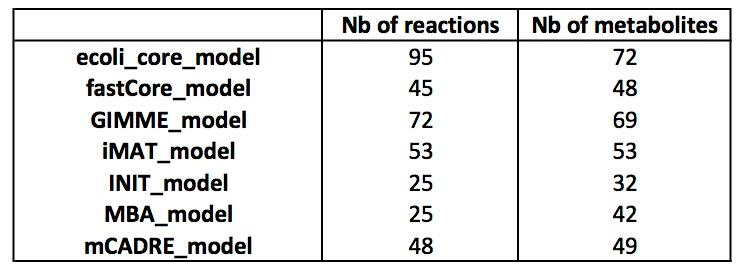

14 reactions are common to the 6 extracted models:

- ACALD	acald[c] + coa[c] + nad[c] 	<=>	accoa[c] + h[c] + nadh[c] 

- ALCD2x	etoh[c] + nad[c] 	<=>	acald[c] + h[c] + nadh[c] 

- ATPS4r	adp[c] + 4 h[e] + pi[c] 	<=>	atp[c] + h2o[c] + 3 h[c] 

- ENO    	2pg[c] 	<=>	h2o[c] + pep[c] 

- FBA	        fdp[c] 	<=>	dhap[c] + g3p[c] 

- GAPD	g3p[c] + nad[c] + pi[c] 	<=>	13dpg[c] + h[c] + nadh[c] 

- GLUDy	glu-L[c] + h2o[c] + nadp[c] 	<=>	akg[c] + h[c] + nadph[c] + nh4[c] 

- GLUSy	akg[c] + gln-L[c] + h[c] + nadph[c] 	->	2 glu-L[c] + nadp[c] 

- PDH    	coa[c] + nad[c] + pyr[c] 	->	accoa[c] + co2[c] + nadh[c] 

- PFK	        atp[c] + f6p[c] 	->	adp[c] + fdp[c] + h[c] 

- PGI	        g6p[c] 	<=>	f6p[c] 

- PGK	        3pg[c] + atp[c] 	<=>	13dpg[c] + adp[c] 

- PYK	        adp[c] + h[c] + pep[c] 	->	atp[c] + pyr[c] 

- TPI	        dhap[c] 	<=>	g3p[c] 

## REFERENCES

*1. Opdam, S,, Richelle, A., Kellman, B., Li, S., Zielinski, D.C., Lewis, N.E. A systematic evaluation of methods for tailoring genome-scale models. Cell Syetms, 4:1-12 (2017).*

*2. Vlassis, N., Pacheco, M.P., and Sauter, T. Fast reconstruction of compact context-specific metabolic network models. PLoS Comput. Biol. 10, e1003424 (2014).*

*3. Becker, S.A., and Palsson, B.O. Context-specific metabolic networks are consistent with experiments. PLoS Comput. Biol. 4, e1000082 (2008).*

*4. Zur, H., Ruppin, E., and Shlomi, T. iMAT: an integrative metabolic anal- ysis tool. Bioinformatics 26, 3140–3142 (2010).*

*5.Agren, R. et al. Reconstruction of genome-scale active metabolic networks for 69 human cell types and 16 cancer types using INIT. PLoS Comput. Biol. 8, e1002518 (2012).*

*6. Jerby, L., Shlomi, T., and Ruppin, E. Computational reconstruction of tissue-specific metabolic models: application to human liver metabolism. Mol. Syst. Biol. 6, 401 (2010). *

*7. Wang, Y., Eddy, J.A., and Price, N.D. Reconstruction of genome-scale metabolic models for 126 human tissues using mCADRE. BMC Syst. Biol. 6, 153 (2012). *

*8. Uhlén M, et al. Tissue-based map of the human proteome. Science, 347(6220):1260419  (2015). *